# とりあえず吉村先生のmainLcUKFqを写経

### `photometric attitude estimation using UKF (quaternion)`

`yoshimuLibrary/examples/estimationLightCurve/mainLcUKFq.mlx`

### `state variables`


$${\bf x}=[{\bf q}^T, {\bf \omega}^T]^T$$


`q`: quaternion where q(4) is the scalar part 

`w`: angular rate, rad/s

### 使う関数(ざっくり)

- yoshimuLibrary/examples/lcUKF.mlx

clc
clear
close all
% cls

curdir = pwd;
addpath(genpath(strcat(curdir, '/../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得
addpath(strcat(curdir, '/../gpryui'));
% addpath(curdir);

### constants

earthVSOP = vsopConst; % VSOP parameters
const = orbitConst; % constants for orbital motion

### simulation conditions

model = 3 % 1: symmetric flat plate, 2: asymmetric inertia flat plate

model = 3

observation = 'mag'; % light curve magnitude or its inverse value

% random number generator
rng(2022, 'twister');

### load true value and set noise

objName.mat = `['t_', 'mApp', 'q', 'phi', 'theta', 'psi', 'w', 'r', 'v', 'obsECI', 'jdHistory', 'sat', 'obsRel', 'sunPosI']` 

if model == 1
    load('flatPlate.mat');
elseif model == 2
    load('flatPlateAsym.mat');
elseif model == 3
    load('boxWing.mat');
end

tn_ = length(t_);
    % sat.nu = ones(length(sat.Cs), 1) .* 300;
    % sat.nv = ones(length(sat.Cs), 1) .* 300;

sigTrue = 0.1; % standard deviation of observation noise
Rtrue = sigTrue^2; % observation noise variance for relative magnitude

### UKF paras. わからん

n_ = 3; % # of state variable := [error GRP and angular rate]

% UKF Parameters
ukfPara.alp = 1e-4;
ukfPara.beta = 2;
ukfPara.kap = 3 - n_;
ukfPara.lam = ukfPara.alp^2 * (n_ + ukfPara.kap) - n_;
ukfPara.lam = 0; % わからん：上書きしてね

ukfPara.w0m = ukfPara.lam / (n_ + ukfPara.lam); % for mean
ukfPara.wim = 1 / (2 * (n_ + ukfPara.lam));
ukfPara.w0c = ukfPara.lam / (n_ + ukfPara.lam) + (1 - ukfPara.alp^2 + ukfPara.beta); % for covariance
ukfPara.wic = ukfPara.wim;

ukfPara.w0m + 2*3*ukfPara.wim

ans = 1

ukfPara.w0c + 2*3*ukfPara.wic

ans = 4.0000


% estimated obsevation noise (standard deviation)
if strcmp(observation, 'mag')
    sigEst = 3 * sigTrue;
    Rest = sigEst.^2; % measurement noise
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
else
    sigEst = 1e-8;
    Rest = sigEst.^2;
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
end

### pre-allocation

xEst = zeros(tn_, n_); % [ error GRP]
p = zeros(tn_, n_); % diagonal components of covariance matrix (Pcov)
qGlobal = zeros(tn_, 4);
ye0 = 0; % わからん
yez = zeros(2*n_, 1);
yeOut = zeros(tn_, 1);

% observations
mAppNoise = mApp + sigTrue .* randn(tn_, 1); % true obs. (relative magnitude)
dTmp = vecnorm(obsRel, 2, 2); % m, distance between sat and observer
mAppInv = magInv(mAppNoise(:, 1), dTmp); % true obs. (relative magnitude inverse)

### initial estimate

% initial estimate
qGlobal(1, :) = q(1, :); % true initial
% large initial error
iniErr = deg2rad(60);
% qGlobal(1,:) = qMult(4, 1, zyx2q(4, iniErr, iniErr, iniErr), q(1,:));
% small initial error
qGlobal(1,:) = qMult(4, 1, zyx2q(4, deg2rad(-10), deg2rad(-10), deg2rad(-10)), q(1,:));

#### initial covariance for 3$\sigma
$ bound

p(1, :) = (iniErr/3)^2 .* ones(1, 3);
Pcov = diag(p(1, :));

% x:= [eror GRP, angular rate]
xEst(1, :) = zeros(1, n_); % 既に0やない？

### Generalized Rodrigues parameters

aGRP = 1;
fGRP = 2 * (aGRP + 1);

## UKF

% modify optical paras.
% sat.F0 = 0.6;
% sat.nu = 800;
% sat.nv = 800;
% sat.Cd = 0.2;

for i = 1:tn_-1
    dt_ = t_(i+1) - t_(i);
    [qGlobal(i+1, :), Pcov] = lcUKF_h(jdHistory(i+1), dt_, xEst(i, :), Pcov, mAppNoise(i+1), ...
        ukfPara, Qest, Rest, fGRP, aGRP, qGlobal(i, :), w(i,:), r(i+1,:), obsECI(i+1,:), sat, const, earthVSOP);
end

xEst = 1.0e-16 *

    0.5201   -0.3614   -0.1850


xEst = 1.0e-16 *

    0.3701   -0.4684   -0.1850


xEst = 1.0e-16 *

   -0.3701    0.6997    0.2776


no observation update


xEst = 1.0e-15 *

    0.1295    0.0526   -0.0278


no observation update


xEst = 1.0e-16 *

   -0.2776    0.0318   -0.6476


no observation update


xEst = 1.0e-15 *

    0.1110    0.0130    0.0093


no observation update


xEst = 1.0e-16 *

    0.5551   -0.0925         0


no observation update


xEst = 1.0e-15 *

    0.1156   -0.0272   -0.0463


no observation update


xEst = 1.0e-16 *

    0.1850   -0.3773   -0.1850


no observation update


xEst = 1.0e-16 *

   -0.4626   -0.1836   -0.1850


no observation update


xEst = 1.0e-16 *

    0.2776   -0.0202    0.1850


no observation update


xEst = 1.0e-16 *

         0   -0.5638   -0.3701


no observation update


xEst = 1.0e-16 *

   -0.2776    0.0542         0


no observation update


xEst = 1.0e-16 *

    0.4626   -0.0499         0


no observation update


xEst = 1.0e-16 *

   -0.4626    0.1872         0


no observation update


xEst = 1.0e-16 *

   -0.0925    0.5193    0.1850


no observation update


xEst = 1.0e-16 *

         0   -0.2291    0.2776


no observation update


xEst = 1.0e-16 *

    0.2313   -0.4611   -0.0925


no observation update


xEst = 1.0e-16 *

    0.4163    0.0406    0.0925


no observation update


xEst = 1.0e-16 *

   -0.6014    0.6717    0.4626


no observation update


xEst = 1.0e-16 *

    0.2776    0.0314    0.0925


no observation update


xEst = 1.0e-16 *

   -0.2313   -0.0954    0.1850


no observation update


xEst = 1.0e-16 *

   -0.3238   -0.1713   -0.0925


no observation update


xEst = 1.0e-16 *

    0.1850   -0.0123   -0.0925


no observation update


xEst = 1.0e-16 *

   -0.0925    0.0492    0.2776


xEst = 1.0e-16 *

    0.2776   -0.5551   -0.0925


xEst = 1.0e-16 *

    0.3469    0.2429    0.3238


xEst = 1.0e-16 *

    0.4279   -0.0231   -0.2313


xEst = 1.0e-16 *

   -0.3065   -0.5667         0


xEst = 1.0e-16 *

    0.2458   -0.1156    0.0694


xEst = 1.0e-16 *

    0.3108    0.0038   -0.0463


xEst = 1.0e-16 *

    0.4713    0.0202    0.0463


xEst = 1.0e-16 *

   -0.1012   -0.0441   -0.0463


xEst = 1.0e-16 *

    0.2458   -0.0846    0.1850


xEst = 1.0e-16 *

   -0.3036   -0.3347   -0.0116


xEst = 1.0e-16 *

   -0.1850    0.0817    0.1503


xEst = 1.0e-17 *

   -0.2891    0.5276   -0.1156


xEst = 1.0e-16 *

    0.1272   -0.0094   -0.1388


xEst = 1.0e-16 *

   -0.0607   -0.5634    0.2197


xEst = 1.0e-16 *

   -0.0636   -0.1717   -0.1966


xEst = 1.0e-16 *

   -0.3455   -0.4651   -0.0116


xEst = 1.0e-16 *

   -0.4872   -0.0683         0


xEst = 1.0e-16 *

    0.5045   -0.1446    0.0578


xEst = 1.0e-16 *

    0.2082    0.2302   -0.0231


xEst = 1.0e-16 *

   -0.1662    0.2277   -0.0752


xEst = 1.0e-16 *

   -0.0014   -0.1301   -0.0925


xEst = 1.0e-16 *

   -0.2299   -0.0083    0.0463


xEst = 1.0e-16 *

   -0.0159   -0.0632    0.2486


xEst = 1.0e-16 *

   -0.1850    0.1081   -0.0752


xEst = 1.0e-16 *

    0.1691   -0.2591   -0.1041


xEst = 1×3
1.0e-17 *

    0.6505    0.1915   -0.7517


xEst = 1×3
1.0e-16 *

    0.0622   -0.4250    0.0520


xEst = 1×3
1.0e-16 *

    0.1171    0.2436    0.0752


xEst = 1×3
1.0e-16 *

    0.2501    0.3910    0.1388


xEst = 1×3
1.0e-16 *

   -0.3759   -0.1464    0.2486


xEst = 1×3
1.0e-16 *

   -0.0029    0.1576    0.0173


xEst = 1×3
1.0e-16 *

   -0.1749   -0.0376   -0.0752


xEst = 1×3
1.0e-16 *

    0.2949   -0.4395   -0.0289


xEst = 1×3
1.0e-16 *

    0.0058   -0.3108    0.3643


xEst = 1×3
1.0e-16 *

   -0.1214   -0.1341   -0.4857


xEst = 1×3
1.0e-16 *

    0.0911   -0.3404   -0.4568


xEst = 1×3
1.0e-16 *

   -0.2284   -0.1037    0.3180


xEst = 1×3
1.0e-16 *

   -0.3636    0.3321    0.3238


xEst = 1×3
1.0e-16 *

   -0.0528   -0.6361    0.2891


xEst = 1×3
1.0e-16 *

   -0.7206   -0.0853   -0.1735


xEst = 1×3
1.0e-16 *

    0.2711   -0.1102   -0.2313


xEst = 1×3
1.0e-16 *

    0.3101    0.1489    0.1099


xEst = 1×3
1.0e-16 *

   -0.2689    0.3025    0.0463


xEst = 1×3
1.0e-16 *

    0.3722    0.0040    0.1619


xEst = 1×3
1.0e-16 *

    0.1265    0.0607    0.1503


xEst = 1×3
1.0e-16 *

   -0.2573   -0.0069   -0.1677


xEst = 1×3
1.0e-16 *

   -0.0080    0.1525   -0.8645


xEst = 1×3
1.0e-16 *

   -0.0195    0.1532   -0.0058


xEst = 1×3
1.0e-16 *

   -0.0557    0.2985    0.1908


xEst = 1×3
1.0e-16 *

    0.0600   -0.0716   -0.4770


xEst = 1×3
1.0e-16 *

    0.1785   -0.1276    0.2631


xEst = 1×3
1.0e-16 *

   -0.1178    0.1514    0.3874


xEst = 1×3
1.0e-16 *

   -0.2602    0.1724    0.0694


xEst = 1×3
1.0e-16 *

   -0.1605   -0.1001   -0.1908


xEst = 1×3
1.0e-17 *

   -0.4265    0.8132    0.8963


xEst = 1×3
1.0e-16 *

    0.0867   -0.1323   -0.2862


xEst = 1×3
1.0e-16 *

    0.1171    0.0477    0.0983


xEst = 1×3
1.0e-16 *

    0.1171   -0.1220   -0.2082


xEst = 1×3
1.0e-16 *

   -0.0405    0.1081    0.0954


xEst = 1×3
1.0e-16 *

    0.1019   -0.0978    0.6563


xEst = 1×3
1.0e-16 *

    0.0134    0.3701    0.6823


xEst = 1×3
1.0e-16 *

    0.1059    0.0660    0.2718


xEst = 1×3
1.0e-16 *

   -0.0842    0.1411   -0.6679


no observation update


xEst = 1×3
1.0e-16 *

   -0.0267   -0.1585   -0.7633


no observation update


xEst = 1×3
1.0e-16 *

    0.0365    0.1243    0.0202


no observation update


xEst = 1×3
1.0e-16 *

    0.2877   -0.3534    0.9165


no observation update


xEst = 1×3
1.0e-16 *

    0.2324    0.1718    0.9368


no observation update


xEst = 1×3
1.0e-16 *

    0.1171   -0.5246    0.4163


no observation update


xEst = 1×3
1.0e-16 *

    0.1894   -0.0452    0.1648


no observation update


xEst = 1×3
1.0e-16 *

    0.0145   -0.0573   -0.4857


no observation update


xEst = 1×3
1.0e-16 *

   -0.1756    0.4106    0.4770


no observation update


xEst = 1×3
1.0e-16 *

   -0.1966    0.2080    0.4799


no observation update


xEst = 1×3
1.0e-16 *

   -0.0119   -0.3489    0.1070


no observation update


xEst = 1×3
1.0e-16 *

    0.0925   -0.1151    0.3643


no observation update


xEst = 1×3
1.0e-16 *

   -0.1077   -0.3153   -0.3730


no observation update


xEst = 1×3
1.0e-17 *

    0.5132    0.3704    0.0867


no observation update


xEst = 1×3
1.0e-16 *

   -0.1308   -0.1476    0.2082


no observation update


xEst = 1×3
1.0e-16 *

    0.1930    0.1706   -0.2053


no observation update


xEst = 1×3
1.0e-16 *

    0.1052    0.1507   -0.1041


no observation update


xEst = 1×3
1.0e-16 *

    0.1905   -0.0477    0.2631


no observation update


xEst = 1×3
1.0e-16 *

   -0.0763    0.0246   -0.7488


no observation update


xEst = 1×3
1.0e-15 *

    0.0241   -0.0112   -0.1214


no observation update


xEst = 1×3
1.0e-16 *

    0.0260    0.7495    0.2660


no observation update


xEst = 1×3
1.0e-15 *

    0.0077    0.0182    0.1107


no observation update


xEst = 1×3
1.0e-16 *

   -0.0098    0.2356    0.2862


no observation update


xEst = 1×3
1.0e-17 *

   -0.5168    0.8204   -0.7806


no observation update


xEst = 1×3
1.0e-16 *

    0.2205    0.1272    0.8095


no observation update


xEst = 1×3
1.0e-16 *

   -0.0123    0.0567    0.8529


no observation update


xEst = 1×3
1.0e-16 *

    0.0383   -0.1308    0.4539


xEst = 1×3
1.0e-16 *

    0.0054   -0.0249   -0.5378


xEst = 1×3
1.0e-15 *

   -0.0065   -0.0098   -0.1084


xEst = 1×3
1.0e-16 *

   -0.0145    0.1655   -0.0058


xEst = 1×3
1.0e-15 *

   -0.0374   -0.0226   -0.1093


xEst = 1×3
1.0e-16 *

   -0.0358    0.0170    0.5551


xEst = 1×3
1.0e-16 *

   -0.1352    0.2429    0.3701


xEst = 1×3
1.0e-16 *

   -0.2356   -0.4201   -0.9035


xEst = 1×3
1.0e-16 *

    0.0197   -0.0045    0.1807


xEst = 1×3
1.0e-16 *

   -0.2309    0.4962    0.9136


xEst = 1×3
1.0e-16 *

    0.1043   -0.3168   -0.7300


xEst = 1×3
1.0e-16 *

   -0.2078    0.0334   -0.9180


xEst = 1×3
1.0e-16 *

   -0.1110   -0.0166    0.5696


xEst = 1×3
1.0e-16 *

   -0.1422    0.2512    0.7416


xEst = 1×3
1.0e-15 *

    0.0219   -0.0615   -0.1285


xEst = 1×3
1.0e-16 *

    0.1990    0.3484    0.3542


xEst = 1×3
1.0e-16 *

   -0.2294   -0.0932    0.3860


xEst = 1×3
1.0e-16 *

   -0.0748    0.1110   -0.1923


xEst = 1×3
1.0e-16 *

   -0.0926   -0.0416   -0.9252


xEst = 1×3
1.0e-16 *

    0.0403   -0.1243   -0.7401


xEst = 1×3
1.0e-15 *

    0.0241   -0.0349   -0.1301


xEst = 1×3
1.0e-15 *

    0.0398   -0.0287    0.2242


xEst = 1×3
1.0e-15 *

   -0.0173    0.0094   -0.2056


xEst = 1×3
1.0e-16 *

    0.1240   -0.2542    0.3831


xEst = 1×3
1.0e-16 *

   -0.0740    0.4124   -0.2053


xEst = 1×3
1.0e-16 *

   -0.0989   -0.0416    0.2082


xEst = 1×3
1.0e-15 *

   -0.0083    0.0389    0.1080


xEst = 1×3
1.0e-16 *

   -0.2176    0.1547    0.3730


xEst = 1×3
1.0e-16 *

   -0.1165   -0.0477   -0.9310


xEst = 1×3
1.0e-16 *

   -0.1274    0.2707    0.3542


xEst = 1×3
1.0e-16 *

    0.0596   -0.1247   -0.1879


xEst = 1×3
1.0e-16 *

   -0.2152   -0.1623   -0.7199


xEst = 1×3
1.0e-15 *

   -0.0189    0.0331    0.1115


xEst = 1×3
1.0e-16 *

   -0.1083    0.0087    0.5840


xEst = 1×3
1.0e-16 *

    0.6468   -0.1641   -0.5956


xEst = 1×3
1.0e-16 *

    0.2582    0.1117    0.1518


xEst = 1×3
1.0e-16 *

   -0.2151    0.5345   -0.2212


xEst = 1×3
1.0e-15 *

   -0.0075    0.0206    0.1302


xEst = 1×3
1.0e-15 *

    0.0123    0.0415    0.1077


xEst = 1×3
1.0e-16 *

    0.0356    0.1319    0.1532


xEst = 1×3
1.0e-16 *

    0.4376   -0.1128    0.7242


xEst = 1×3
1.0e-16 *

    0.2135    0.1160   -0.7835


xEst = 1×3
1.0e-16 *

    0.3174   -0.0737    0.1778


xEst = 1×3
1.0e-15 *

    0.0084   -0.0054    0.1305


xEst = 1×3
1.0e-16 *

    0.4906   -0.1688   -0.3932


xEst = 1×3
1.0e-16 *

   -0.0674    0.3368   -0.6014


xEst = 1×3
1.0e-16 *

   -0.0628    0.1138    0.1691


xEst = 1×3
1.0e-16 *

   -0.2119   -0.0994   -0.1749


xEst = 1×3
1.0e-15 *

   -0.0068    0.0134    0.1496


xEst = 1×3
1.0e-15 *

   -0.0488   -0.0013   -0.1479


xEst = 1×3
1.0e-16 *

    0.4593   -0.0763   -0.4106


xEst = 1×3
1.0e-16 *

   -0.1994    0.1861   -0.3874


xEst = 1×3
1.0e-16 *

    0.1314   -0.2385    0.2096


xEst = 1×3
1.0e-16 *

   -0.1052   -0.0535   -0.1706


xEst = 1×3
1.0e-16 *

   -0.0184    0.2411    0.5320


xEst = 1×3
1.0e-16 *

   -0.1298   -0.1023    0.5941


xEst = 1×3
1.0e-16 *

   -0.1487   -0.2494   -0.3513


xEst = 1×3
1.0e-16 *

   -0.3476   -0.0589    0.3961


xEst = 1×3
1.0e-16 *

    0.7044   -0.0083   -0.4019


xEst = 1×3
1.0e-16 *

    0.1259   -0.1850   -0.1749


xEst = 1×3
1.0e-16 *

    0.1825    0.5096   -0.6274


xEst = 1×3
1.0e-16 *

   -0.3146   -0.0231    0.4062


xEst = 1×3
1.0e-16 *

    0.3801    0.2035   -0.6086


xEst = 1×3
1.0e-16 *

    0.0938    0.5215    0.5117


xEst = 1×3
1.0e-16 *

   -0.3177    0.0611    0.2096


xEst = 1×3
1.0e-16 *

    0.0112    0.2335    0.5305


xEst = 1×3
1.0e-16 *

    0.2272    0.0278    0.5407


xEst = 1×3
1.0e-16 *

   -0.0186   -0.0159    0.2038


xEst = 1×3
1.0e-15 *

   -0.0166   -0.0004    0.1142


xEst = 1×3
1.0e-15 *

   -0.0016   -0.0025    0.1125


xEst = 1×3
1.0e-16 *

    0.0220   -0.0802   -0.5623


xEst = 1×3
1.0e-16 *

    0.1347    0.0546   -0.7503


xEst = 1×3
1.0e-16 *

    0.1298   -0.1261    0.1937


xEst = 1×3
1.0e-16 *

   -0.1265    0.2591    0.5305


xEst = 1×3
1.0e-16 *

   -0.0785   -0.0376   -0.7546


xEst = 1×3
1.0e-15 *

    0.0145   -0.0569   -0.1279


xEst = 1×3
1.0e-16 *

   -0.1329    0.1973    0.1576


xEst = 1×3
1.0e-16 *

   -0.1860   -0.1131    0.2226


xEst = 1×3
1.0e-16 *

    0.1000    0.1117    0.7387


xEst = 1×3
1.0e-15 *

    0.0250    0.0508    0.1612


xEst = 1×3
1.0e-16 *

    0.2574   -0.2291    0.0116


xEst = 1×3
1.0e-15 *

    0.0162   -0.0051   -0.1508


xEst = 1×3
1.0e-16 *

    0.0710   -0.0405   -0.7604


xEst = 1×3
1.0e-16 *

    0.1185   -0.4366    0.0752


xEst = 1×3
1.0e-15 *

   -0.0201    0.0405    0.1451


xEst = 1×3
1.0e-16 *

    0.1299   -0.4351   -0.5031


xEst = 1×3
1.0e-16 *

    0.2642    0.3426    0.1258


xEst = 1×3
1.0e-16 *

   -0.3588    0.0958   -0.7748


xEst = 1×3
1.0e-15 *

   -0.0105    0.0122    0.1502


xEst = 1×3
1.0e-16 *

    0.3029    0.3773    0.5074


xEst = 1×3
1.0e-16 *

   -0.1922   -0.2190    0.9917


xEst = 1×3
1.0e-16 *

   -0.3235   -0.0777   -0.1446


xEst = 1×3
1.0e-16 *

   -0.1315   -0.0712    0.1865


xEst = 1×3
1.0e-16 *

   -0.0381   -0.0651   -0.3455


xEst = 1×3
1.0e-16 *

   -0.0438    0.5739    0.8674


xEst = 1×3
1.0e-15 *

    0.0113   -0.0068   -0.2664


xEst = 1×3
1.0e-15 *

   -0.0498   -0.0181   -0.2044


xEst = 1×3
1.0e-15 *

   -0.0053   -0.0091   -0.2278


xEst = 1×3
1.0e-16 *

   -0.2691    0.0647    0.7561


xEst = 1×3
1.0e-16 *

    0.4323    0.3025    0.9093


xEst = 1×3
1.0e-15 *

   -0.0047   -0.0197   -0.2060


xEst = 1×3
1.0e-16 *

    0.4355    0.1908    0.3339


xEst = 1×3
1.0e-15 *

    0.0033    0.0347    0.1830


xEst = 1×3
1.0e-16 *

    0.3315   -0.3314    0.2617


xEst = 1×3
1.0e-15 *

    0.0726   -0.0316   -0.2601


xEst = 1×3
1.0e-15 *

   -0.0094   -0.0164   -0.1291


xEst = 1×3
1.0e-16 *

   -0.0861   -0.1276   -0.5753


xEst = 1×3
1.0e-16 *

   -0.0718   -0.2761   -0.9180


xEst = 1×3
1.0e-15 *

   -0.0290   -0.0338   -0.1246


xEst = 1×3
1.0e-16 *

    0.5030    0.1554    0.3600


xEst = 1×3
1.0e-15 *

    0.0228   -0.0053    0.1321


xEst = 1×3
1.0e-15 *

    0.0222   -0.0244   -0.1464


xEst = 1×3
1.0e-16 *

   -0.0806   -0.0524   -0.7589


xEst = 1×3
1.0e-15 *

   -0.0484   -0.0228    0.1168


xEst = 1×3
1.0e-15 *

   -0.0206   -0.0172   -0.1477


xEst = 1×3
1.0e-16 *

   -0.1306   -0.2819   -0.6982


xEst = 1×3
1.0e-15 *

    0.0620    0.0319    0.1843


xEst = 1×3
1.0e-16 *

   -0.1728    0.2830    0.5132


xEst = 1×3
1.0e-16 *

    0.0352    0.1467   -0.0260


xEst = 1×3
1.0e-16 *

    0.3991   -0.0871    0.1807


xEst = 1×3
1.0e-16 *

    0.2830   -0.0119    0.5392


xEst = 1×3
1.0e-16 *

    0.1839   -0.1814   -0.7286


xEst = 1×3
1.0e-16 *

   -0.7649   -0.3787    0.3036


xEst = 1×3
1.0e-16 *

    0.0440    0.0582    0.5450


xEst = 1×3
1.0e-15 *

    0.0143   -0.0486   -0.1837


xEst = 1×3
1.0e-16 *

   -0.3957   -0.3722   -0.4973


xEst = 1×3
1.0e-15 *

   -0.0012    0.0206   -0.1570


xEst = 1×3
1.0e-15 *

    0.0492    0.0153   -0.2364


xEst = 1×3
1.0e-16 *

    0.3022    0.2804    0.3657


xEst = 1×3
1.0e-16 *

    0.3717    0.5049    0.0838


xEst = 1×3
1.0e-15 *

   -0.0498   -0.0162    0.1382


xEst = 1×3
1.0e-16 *

    0.9027    0.0206    0.7777


xEst = 1×3
1.0e-15 *

   -0.0171   -0.0369   -0.1664


xEst = 1×3
1.0e-16 *

    0.2433   -0.5309   -0.2906


xEst = 1×3
1.0e-15 *

   -0.0863   -0.0221   -0.2255


xEst = 1×3
1.0e-16 *

    0.8115   -0.2425    0.2443


xEst = 1×3
1.0e-15 *

    0.0551   -0.0474    0.1061


xEst = 1×3
1.0e-15 *

    0.0631    0.1015    0.0958


xEst = 1×3
1.0e-15 *

   -0.0804   -0.0059   -0.1149


xEst = 1×3
1.0e-16 *

    0.4683    0.8677   -0.2212


xEst = 1×3
1.0e-16 *

   -0.3034    0.7405    0.6404


xEst = 1×3
1.0e-16 *

   -0.5840    0.1521   -0.1966


xEst = 1×3
1.0e-15 *

    0.0151   -0.0030    0.1920


xEst = 1×3
1.0e-16 *

   -0.4995    0.0228   -0.7387


xEst = 1×3
1.0e-15 *

   -0.0212   -0.0329   -0.1874


xEst = 1×3
1.0e-16 *

    0.7523    0.4471   -0.0882


xEst = 1×3
1.0e-16 *

    0.3989   -0.1370    0.2270


xEst = 1×3
1.0e-16 *

    0.5235   -0.7448   -0.4597


xEst = 1×3
1.0e-16 *

   -0.1612    0.4926    0.4655


xEst = 1×3
1.0e-15 *

    0.1141    0.0528    0.0474


xEst = 1×3
1.0e-15 *

    0.0102   -0.0319   -0.1482


xEst = 1×3
1.0e-15 *

   -0.1224    0.0464   -0.0269


xEst = 1×3
1.0e-16 *

    0.0623   -0.0958   -0.4033


xEst = 1×3
1.0e-16 *

    0.4365    0.6006    0.8529


xEst = 1×3
1.0e-16 *

   -0.2246   -0.8359    0.3932


xEst = 1×3
1.0e-15 *

   -0.1091    0.0049   -0.1978


xEst = 1×3
1.0e-15 *

   -0.0062   -0.0180   -0.1310


xEst = 1×3
1.0e-16 *

   -0.3865    0.8312    0.2053


xEst = 1×3
1.0e-16 *

    0.1950    0.5974    0.2862


xEst = 1×3
1.0e-16 *

    0.4774    0.1742    0.5725


xEst = 1×3
1.0e-15 *

   -0.0017    0.0329    0.1467


xEst = 1×3
1.0e-16 *

   -0.4452   -0.0972   -0.5508


xEst = 1×3
1.0e-16 *

    0.0501   -0.1511    0.6043


xEst = 1×3
1.0e-16 *

   -0.2188    0.3169    0.7633


xEst = 1×3
1.0e-16 *

    0.4561    0.6400    0.8327


xEst = 1×3
1.0e-16 *

    0.1140   -0.3325    0.0708


xEst = 1×3
1.0e-16 *

    0.0423   -0.0394   -0.7850


xEst = 1×3
1.0e-15 *

   -0.0265    0.0150    0.1136


xEst = 1×3
1.0e-16 *

   -0.4792   -0.2349    0.0679


xEst = 1×3
1.0e-16 *

    0.1053   -0.3249   -0.3094


xEst = 1×3
1.0e-16 *

    0.7714    0.0593   -0.1749


xEst = 1×3
1.0e-16 *

   -0.4494   -0.1977    0.2429


xEst = 1×3
1.0e-15 *

   -0.0953    0.0501    0.1644


xEst = 1×3
1.0e-15 *

    0.0542   -0.0314   -0.1675


xEst = 1×3
1.0e-16 *

   -0.6026    0.5186    0.4886


xEst = 1×3
1.0e-15 *

    0.0224   -0.0460   -0.2809


xEst = 1×3
1.0e-16 *

   -0.5029    0.0036    0.0014


xEst = 1×3
1.0e-15 *

   -0.0914    0.0840    0.2907


xEst = 1×3
1.0e-16 *

   -0.3139   -0.0007   -0.1937


xEst = 1×3
1.0e-16 *

    0.2291    0.4174    0.5132


xEst = 1×3
1.0e-15 *

   -0.1267    0.0533    0.2796


xEst = 1×3
1.0e-16 *

   -0.4731   -0.5949   -0.6708


xEst = 1×3
1.0e-16 *

   -0.7270    0.6458    0.6100


xEst = 1×3
1.0e-16 *

    0.5979    0.2407   -0.2443


xEst = 1×3
1.0e-16 *

    0.0345    0.0390   -0.4149


xEst = 1×3
1.0e-16 *

    0.5289    0.4004   -0.4496


xEst = 1×3
1.0e-16 *

    0.8276   -0.5056    0.5305


xEst = 1×3
1.0e-15 *

   -0.0003   -0.0975   -0.1149


xEst = 1×3
1.0e-15 *

   -0.0098    0.0104   -0.2022


xEst = 1×3
1.0e-16 *

    0.2763   -0.0126    0.4944


xEst = 1×3
1.0e-15 *

    0.0632    0.0495    0.1068


xEst = 1×3
1.0e-16 *

   -0.4845    0.1561   -0.6838


xEst = 1×3
1.0e-16 *

    0.3795   -0.2931   -0.2920


xEst = 1×3
1.0e-15 *

    0.0160   -0.0601   -0.1424


xEst = 1×3
1.0e-16 *

    0.6091   -0.3216   -0.4481


xEst = 1×3
1.0e-16 *

   -0.2145   -0.0791   -0.4236


xEst = 1×3
1.0e-16 *

   -0.7922   -0.6003    0.6896


xEst = 1×3
1.0e-16 *

   -0.6364   -0.6505   -0.6462


xEst = 1×3
1.0e-15 *

    0.0031    0.0438    0.1288


xEst = 1×3
1.0e-15 *

   -0.0630    0.1007    0.0734


xEst = 1×3
1.0e-15 *

   -0.0450    0.0499    0.2777


xEst = 1×3
1.0e-16 *

    0.1245    0.2458   -0.2689


xEst = 1×3
1.0e-15 *

   -0.0178    0.1207   -0.0685


xEst = 1×3
1.0e-16 *

    0.0499   -0.2656    0.0390


xEst = 1×3
1.0e-15 *

   -0.0403    0.1070    0.0383


xEst = 1×3
1.0e-16 *

   -0.2994   -0.4817    0.2645


xEst = 1×3
1.0e-16 *

    0.7022   -0.0473   -0.7300


xEst = 1×3
1.0e-16 *

   -0.0985   -0.1153   -0.7604


xEst = 1×3
1.0e-15 *

   -0.0260   -0.0523   -0.1120


xEst = 1×3
1.0e-16 *

    0.1276    0.1099   -0.8081


xEst = 1×3
1.0e-16 *

   -0.2727    0.9678    0.5378


xEst = 1×3
1.0e-15 *

    0.0116    0.0023   -0.1000


xEst = 1×3
1.0e-15 *

   -0.0285   -0.0696   -0.2809


xEst = 1×3
1.0e-16 *

    0.2913   -0.4590   -0.8225


xEst = 1×3
1.0e-16 *

    0.2429   -0.5237    0.7561


xEst = 1×3
1.0e-15 *

    0.0382    0.0464    0.2459


xEst = 1×3
1.0e-15 *

    0.0503   -0.0613   -0.1041


xEst = 1×3
1.0e-15 *

   -0.0437    0.0014   -0.1185


xEst = 1×3
1.0e-15 *

    0.0522    0.0559    0.1438


xEst = 1×3
1.0e-16 *

    0.2947   -0.3397   -0.3441


xEst = 1×3
1.0e-16 *

   -0.4115   -0.7597   -0.4626


xEst = 1×3
1.0e-16 *

   -0.4386    0.6494    0.8312


xEst = 1×3
1.0e-15 *

    0.1007    0.0336    0.0376


xEst = 1×3
1.0e-15 *

   -0.0691    0.0497    0.1790


xEst = 1×3
1.0e-15 *

    0.0403   -0.0445   -0.1433


xEst = 1×3
1.0e-16 *

   -0.1306   -0.3596    0.2935


xEst = 1×3
1.0e-16 *

   -0.6769    0.3813   -0.6751


xEst = 1×3
1.0e-16 *

    0.6588   -0.4781   -0.4611


xEst = 1×3
1.0e-15 *

   -0.0494    0.0418    0.1000


xEst = 1×3
1.0e-15 *

   -0.1167   -0.0236    0.0739


xEst = 1×3
1.0e-16 *

   -0.5468   -0.1887   -0.7879


xEst = 1×3
1.0e-15 *

    0.1005    0.0487    0.2307


xEst = 1×3
1.0e-15 *

   -0.0260   -0.0059   -0.1435


xEst = 1×3
1.0e-16 *

   -0.8431   -0.5840   -0.4626


xEst = 1×3
1.0e-15 *

   -0.1454   -0.0923   -0.0896


xEst = 1×3
1.0e-15 *

   -0.0428   -0.0044    0.1182


xEst = 1×3
1.0e-15 *

   -0.0837   -0.0142    0.1174


xEst = 1×3
1.0e-16 *

   -0.2199   -0.0679   -0.7893


xEst = 1×3
1.0e-15 *

   -0.0056    0.0432    0.1065


xEst = 1×3
1.0e-16 *

    0.5398    0.0025    0.0571


xEst = 1×3
1.0e-15 *

   -0.0691    0.0343    0.1657


xEst = 1×3
1.0e-15 *

   -0.0459    0.0790    0.1676


xEst = 1×3
1.0e-15 *

   -0.1391   -0.0078   -0.0645


xEst = 1×3
1.0e-15 *

   -0.0049    0.0396   -0.1031


xEst = 1×3
1.0e-15 *

    0.0060    0.0510    0.2187


xEst = 1×3
1.0e-15 *

   -0.0255   -0.0277   -0.1108


xEst = 1×3
1.0e-16 *

    0.7918    0.8789    0.0557


xEst = 1×3
1.0e-16 *

    0.4049    0.0278   -0.3542


xEst = 1×3
1.0e-15 *

   -0.0019   -0.0506   -0.1481


xEst = 1×3
1.0e-16 *

   -0.3549   -0.3679   -0.5920


xEst = 1×3
1.0e-15 *

   -0.1121   -0.0884   -0.1845


xEst = 1×3
1.0e-16 *

   -0.0846   -0.2143   -0.5276


xEst = 1×3
1.0e-16 *

   -0.4577    0.1059    0.3585


xEst = 1×3
1.0e-16 *

    0.6062   -0.1825   -0.0940


xEst = 1×3
1.0e-16 *

    0.7360   -0.4138   -0.4207


xEst = 1×3
1.0e-15 *

    0.0138    0.0117    0.1786


xEst = 1×3
1.0e-15 *

   -0.0051    0.0277    0.2099


xEst = 1×3
1.0e-15 *

   -0.0467    0.0998    0.1308


xEst = 1×3
1.0e-16 *

   -0.0941   -0.1182    0.3809


xEst = 1×3
1.0e-15 *

   -0.0048   -0.0026    0.2133


xEst = 1×3
1.0e-15 *

   -0.0007   -0.0117    0.3154


xEst = 1×3
1.0e-15 *

    0.0303   -0.0387    0.1263


xEst = 1×3
1.0e-16 *

   -0.5963   -0.0332   -0.9845


xEst = 1×3
1.0e-16 *

   -0.2730   -0.4760   -0.3368


xEst = 1×3
1.0e-16 *

    0.3630    0.3672    0.3390


xEst = 1×3
1.0e-15 *

   -0.0511    0.0603    0.1184


xEst = 1×3
1.0e-15 *

    0.1061    0.0354   -0.0151


xEst = 1×3
1.0e-16 *

    0.0529    0.3282   -0.2638


xEst = 1×3
1.0e-16 *

   -0.1334    0.6115   -0.1706


xEst = 1×3
1.0e-16 *

   -0.3139    0.0426   -0.2306


xEst = 1×3
1.0e-16 *

    0.1408    0.6028    0.8927


xEst = 1×3
1.0e-16 *

    0.2814   -0.2786   -0.8876


xEst = 1×3
1.0e-15 *

   -0.0319    0.0232    0.1254


xEst = 1×3
1.0e-15 *

    0.0409   -0.0418   -0.1609


xEst = 1×3
1.0e-15 *

   -0.0455   -0.0809   -0.1450


xEst = 1×3
1.0e-15 *

   -0.0182   -0.0205    0.1772


xEst = 1×3
1.0e-15 *

   -0.0155   -0.0668   -0.1279


xEst = 1×3
1.0e-15 *

    0.0279    0.1363    0.2133


xEst = 1×3
1.0e-16 *

    0.4321    0.0181    0.0520


xEst = 1×3
1.0e-15 *

    0.0576   -0.0139   -0.1079


xEst = 1×3
1.0e-16 *

   -0.1634    0.6017    0.6418


xEst = 1×3
1.0e-16 *

    0.0672    0.3455    0.5038


xEst = 1×3
1.0e-16 *

    0.0154    0.4633    0.1077


xEst = 1×3
1.0e-16 *

    0.4158    0.4283    0.9461


xEst = 1×3
1.0e-16 *

   -0.0107    0.2215    0.3412


xEst = 1×3
1.0e-16 *

   -0.4519   -0.7521    0.2711


xEst = 1×3
1.0e-16 *

    0.3762    0.6393    0.3722


xEst = 1×3
1.0e-16 *

    0.0531   -0.5923   -0.2927


xEst = 1×3
1.0e-16 *

    0.3965    0.0394    0.2342


xEst = 1×3
1.0e-16 *

    0.0726    0.1681   -0.3932


xEst = 1×3
1.0e-16 *

    0.2306   -0.1977   -0.3289


xEst = 1×3
1.0e-16 *

    0.1948    0.0257    0.1865


xEst = 1×3
1.0e-16 *

   -0.5356    0.3553    0.2602


xEst = 1×3
1.0e-16 *

   -0.0712    0.1120   -0.5819


xEst = 1×3
1.0e-16 *

    0.3489    0.0578   -0.1793


xEst = 1×3
1.0e-16 *

    0.1818    0.1746    0.7495


xEst = 1×3
1.0e-16 *

   -0.2848   -0.0922   -0.4380


xEst = 1×3
1.0e-16 *

   -0.3444   -0.6700   -0.9021


xEst = 1×3
1.0e-15 *

    0.0156    0.0264    0.1318


xEst = 1×3
1.0e-16 *

    0.0549   -0.2953    0.2313


xEst = 1×3
1.0e-16 *

   -0.4592   -0.6418    0.3759


xEst = 1×3
1.0e-16 *

   -0.3464   -0.1623    0.3975


xEst = 1×3
1.0e-16 *

    0.4198   -0.0842   -0.2884


xEst = 1×3
1.0e-16 *

   -0.1041   -0.2335    0.4669


xEst = 1×3
1.0e-16 *

   -0.0690    0.3014    0.1431


xEst = 1×3
1.0e-16 *

   -0.3012   -0.8323   -0.5211


xEst = 1×3
1.0e-16 *

   -0.2976   -0.6447   -0.5479


xEst = 1×3
1.0e-16 *

    0.1147   -0.1041   -0.5710


xEst = 1×3
1.0e-16 *

    0.1881    0.3708    0.3657


xEst = 1×3
1.0e-15 *

    0.0393    0.0381    0.1161


xEst = 1×3
1.0e-15 *

   -0.0108    0.0249    0.1060


xEst = 1×3
1.0e-16 *

   -0.0510   -0.1619   -0.4055


xEst = 1×3
1.0e-16 *

   -0.5959   -0.9483   -0.7192


xEst = 1×3
1.0e-16 *

   -0.0249   -0.3578   -0.1453


xEst = 1×3
1.0e-16 *

    0.7884    0.7514    0.7640


xEst = 1×3
1.0e-16 *

    0.4375    0.0896   -0.3571


xEst = 1×3
1.0e-16 *

    0.1413   -0.2649   -0.3000


xEst = 1×3
1.0e-16 *

   -0.0696   -0.4499   -0.3000


xEst = 1×3
1.0e-16 *

   -0.1462   -0.2667    0.1959


xEst = 1×3
1.0e-16 *

   -0.1793   -0.0101   -0.4373


xEst = 1×3
1.0e-16 *

   -0.0737    0.7391    0.4922


xEst = 1×3
1.0e-15 *

   -0.0221    0.0035    0.1327


xEst = 1×3
1.0e-15 *

    0.0123    0.0409    0.1159


xEst = 1×3
1.0e-16 *

    0.3679    0.6133   -0.6021


xEst = 1×3
1.0e-16 *

    0.1841    0.4167   -0.0354


xEst = 1×3
1.0e-15 *

   -0.0112   -0.0783   -0.1274


xEst = 1×3
1.0e-16 *

    0.0922   -0.5435   -0.8927


xEst = 1×3
1.0e-16 *

   -0.1720   -0.2566    0.5790


xEst = 1×3
1.0e-16 *

   -0.1549    0.3422    0.1460


xEst = 1×3
1.0e-16 *

   -0.1317   -0.0932   -0.2009


xEst = 1×3
1.0e-15 *

    0.0420   -0.0312   -0.1083


xEst = 1×3
1.0e-16 *

    0.4933    0.0567    0.6418


xEst = 1×3
1.0e-15 *

   -0.0492   -0.1180   -0.0718


xEst = 1×3
1.0e-16 *

    0.0788   -0.0936    0.2089


xEst = 1×3
1.0e-16 *

    0.3516   -0.0340   -0.6932


xEst = 1×3
1.0e-16 *

   -0.0678    0.8182    0.8442


xEst = 1×3
1.0e-16 *

   -0.1070   -0.3224    0.0181


xEst = 1×3
1.0e-16 *

   -0.0660   -0.3813   -0.5501


xEst = 1×3
1.0e-15 *

   -0.0247   -0.0137    0.1729


xEst = 1×3
1.0e-16 *

   -0.0698    0.1044    0.0014


xEst = 1×3
1.0e-15 *

    0.0222    0.1053    0.0082


xEst = 1×3
1.0e-16 *

   -0.1747    0.4673   -0.6961


xEst = 1×3
1.0e-16 *

    0.0522   -0.1135    0.5913


xEst = 1×3
1.0e-16 *

    0.4185    0.1753   -0.9324


xEst = 1×3
1.0e-16 *

    0.0220   -0.4857   -0.1626


xEst = 1×3
1.0e-16 *

   -0.2570    0.2992   -0.4908


xEst = 1×3
1.0e-16 *

   -0.0640   -0.6563    0.8544


xEst = 1×3
1.0e-16 *

    0.1594    0.7275    0.0918


xEst = 1×3
1.0e-16 *

   -0.6064   -0.0690    0.6953


xEst = 1×3
1.0e-16 *

   -0.1612   -0.3592    0.2306


xEst = 1×3
1.0e-16 *

    0.3498    0.0947   -0.9396


xEst = 1×3
1.0e-16 *

   -0.2548    0.3939    0.8818


xEst = 1×3
1.0e-16 *

    0.3516    0.4073   -0.5768


xEst = 1×3
1.0e-16 *

   -0.1142    0.5782    0.8594


xEst = 1×3
1.0e-16 *

   -0.4431   -0.2895   -0.6035


xEst = 1×3
1.0e-16 *

    0.1872   -0.0235   -0.1547


xEst = 1×3
1.0e-16 *

   -0.1453    0.6191    0.1330


xEst = 1×3
1.0e-16 *

   -0.0004   -0.0575    0.3867


xEst = 1×3
1.0e-16 *

   -0.3039   -0.8352    0.9498


xEst = 1×3
1.0e-16 *

    0.1619   -0.1883    0.1908


xEst = 1×3
1.0e-15 *

    0.0436    0.0181   -0.1014


xEst = 1×3
1.0e-15 *

   -0.0056    0.1132    0.1224


xEst = 1×3
1.0e-16 *

    0.7994    0.6502    0.1178


xEst = 1×3
1.0e-16 *

   -0.0835   -0.7564   -0.4409


xEst = 1×3
1.0e-16 *

    0.0170   -0.2237   -0.4619


xEst = 1×3
1.0e-16 *

    0.1334   -0.1554   -0.2364


xEst = 1×3
1.0e-16 *

    0.3039    0.2313    0.2031


xEst = 1×3
1.0e-16 *

   -0.2031    0.1446   -0.1749


xEst = 1×3
1.0e-16 *

   -0.3300    0.1760   -0.4705


xEst = 1×3
1.0e-16 *

   -0.0871   -0.3943   -0.6390


xEst = 1×3
1.0e-16 *

    0.0632   -0.4022   -0.6455


xEst = 1×3
1.0e-16 *

    0.1305    0.8486    0.3130


xEst = 1×3
1.0e-16 *

    0.0267   -0.5197   -0.7864


xEst = 1×3
1.0e-16 *

   -0.4857   -0.8670   -0.1858


xEst = 1×3
1.0e-16 *

   -0.4438   -0.1941    0.1409


xEst = 1×3
1.0e-16 *

    0.4181    0.3282    0.8153


xEst = 1×3
1.0e-16 *

    0.1944    0.6285    0.0376


xEst = 1×3
1.0e-16 *

   -0.0481   -0.2786    0.3318


xEst = 1×3
1.0e-16 *

   -0.3003   -0.3343   -0.6014


xEst = 1×3
1.0e-16 *

    0.4116    0.8768   -0.0434


xEst = 1×3
1.0e-16 *

   -0.1872   -0.5511   -0.3694


xEst = 1×3
1.0e-16 *

   -0.0651    0.1099   -0.0036


xEst = 1×3
1.0e-16 *

   -0.0918   -0.5602    0.1214


xEst = 1×3
1.0e-16 *

    0.5475    0.1785   -0.1142


xEst = 1×3
1.0e-16 *

    0.1865   -0.3329   -0.5479


xEst = 1×3
1.0e-15 *

   -0.0537   -0.1356   -0.0364


xEst = 1×3
1.0e-16 *

    0.2331   -0.4510    0.3057


xEst = 1×3
1.0e-16 *

   -0.1362   -0.4709   -0.3282


xEst = 1×3
1.0e-16 *

    0.0177   -0.9877   -0.5566


xEst = 1×3
1.0e-16 *

   -0.1424    0.4348   -0.3896


xEst = 1×3
1.0e-16 *

    0.1196   -0.2233   -0.2450


xEst = 1×3
1.0e-16 *

   -0.1460    0.1052   -0.4286


xEst = 1×3
1.0e-16 *

    0.5898    0.4705   -0.1012


xEst = 1×3
1.0e-16 *

   -0.2114    0.5378    0.1793


xEst = 1×3
1.0e-16 *

   -0.1124    0.5876    0.0390


xEst = 1×3
1.0e-15 *

   -0.0441   -0.1184   -0.0427


xEst = 1×3
1.0e-16 *

   -0.2027   -0.3600    0.1366


xEst = 1×3
1.0e-16 *

   -0.1590    0.1214    0.1561


xEst = 1×3
1.0e-16 *

   -0.3668   -0.6057   -0.2190


xEst = 1×3
1.0e-16 *

   -0.1395    0.2197    0.1511


xEst = 1×3
1.0e-16 *

   -0.4265   -0.1782    0.3903


xEst = 1×3
1.0e-15 *

    0.0227    0.1099   -0.0157


xEst = 1×3
1.0e-16 *

   -0.0051   -0.1218   -0.3643


xEst = 1×3
1.0e-16 *

    0.0502    0.0799    0.2197


xEst = 1×3
1.0e-16 *

    0.1576   -0.1019   -0.0752


xEst = 1×3
1.0e-16 *

    0.0557    0.1041    0.0679


xEst = 1×3
1.0e-16 *

    0.1659    0.2573   -0.0882


xEst = 1×3
1.0e-16 *

   -0.3097   -0.4380   -0.3404


xEst = 1×3
1.0e-16 *

   -0.0694   -0.3954   -0.3694


xEst = 1×3
1.0e-16 *

    0.2880    0.6021   -0.4330


xEst = 1×3
1.0e-16 *

    0.4228   -0.0054   -0.5811


xEst = 1×3
1.0e-16 *

   -0.2349    0.0343   -0.0557


xEst = 1×3
1.0e-16 *

    0.0361    0.0979    0.2024


xEst = 1×3
1.0e-16 *

   -0.3686   -0.2378   -0.1995


xEst = 1×3
1.0e-16 *

    0.0799    0.6534    0.0578


xEst = 1×3
1.0e-16 *

   -0.0452   -0.6541   -0.0448


xEst = 1×3
1.0e-16 *

    0.3408    0.4315   -0.0918


xEst = 1×3
1.0e-16 *

   -0.1287    0.2009    0.1229


xEst = 1×3
1.0e-16 *

   -0.0618   -0.2779   -0.2132


xEst = 1×3
1.0e-16 *

   -0.0387   -0.3748    0.0029


xEst = 1×3
1.0e-16 *

    0.0300   -0.2743   -0.0390


xEst = 1×3
1.0e-16 *

    0.0210    0.2678   -0.1156


xEst = 1×3
1.0e-16 *

   -0.1868   -0.3694   -0.0412


xEst = 1×3
1.0e-16 *

    0.0235   -0.2963    0.0137


xEst = 1×3
1.0e-16 *

    0.0914   -0.0828    0.3939


xEst = 1×3
1.0e-16 *

    0.2794    0.0690    0.1214


xEst = 1×3
1.0e-16 *

   -0.0332    0.0134    0.1099


xEst = 1×3
1.0e-16 *

   -0.4803   -0.9241   -0.3983


xEst = 1×3
1.0e-16 *

   -0.0108   -0.1959   -0.0983


xEst = 1×3
1.0e-16 *

    0.2429   -0.1008    0.1438


xEst = 1×3
1.0e-16 *

   -0.1207   -0.5399    0.1366


xEst = 1×3
1.0e-16 *

    0.1753    0.0799    0.0860


xEst = 1×3
1.0e-16 *

   -0.0188   -0.3806   -0.0810


xEst = 1×3
1.0e-16 *

   -0.0448   -0.5432    0.1402


xEst = 1×3
1.0e-16 *

   -0.0846   -0.0141   -0.3238


xEst = 1×3
1.0e-16 *

    0.0036   -0.1041   -0.1063


xEst = 1×3
1.0e-15 *

    0.0204    0.1023    0.0071


xEst = 1×3
1.0e-16 *

   -0.1012   -0.1706    0.1265


xEst = 1×3
1.0e-16 *

   -0.0231    0.7470    0.0318


xEst = 1×3
1.0e-16 *

   -0.5302   -0.0651   -0.1431


xEst = 1×3
1.0e-16 *

    0.2573    0.1738   -0.0159


xEst = 1×3
1.0e-16 *

    0.1948    0.0925    0.0058


xEst = 1×3
1.0e-16 *

    0.1742   -0.0173   -0.0340


xEst = 1×3
1.0e-16 *

   -0.3079    0.1091   -0.0470


xEst = 1×3
1.0e-16 *

   -0.2020   -0.1847   -0.1207


xEst = 1×3
1.0e-16 *

    0.0152    0.5584   -0.0629


xEst = 1×3
1.0e-16 *

   -0.4149   -0.4536   -0.1026


xEst = 1×3
1.0e-15 *

   -0.0143   -0.1010    0.0064


xEst = 1×3
1.0e-16 *

   -0.1659    0.6455   -0.1070


xEst = 1×3
1.0e-16 *

    0.1608    0.1829    0.0123


xEst = 1×3
1.0e-16 *

   -0.3032    0.1901   -0.1554


xEst = 1×3
1.0e-16 *

    0.2009    0.1840    0.1077


xEst = 1×3
1.0e-16 *

   -0.1077    0.6549   -0.0600


xEst = 1×3
1.0e-17 *

   -0.2819   -0.0795   -0.4192


xEst = 1×3
1.0e-16 *

   -0.1576   -0.0051   -0.0282


xEst = 1×3
1.0e-16 *

   -0.0690    0.4655    0.0022


xEst = 1×3
1.0e-16 *

    0.0235   -0.2765    0.0210


xEst = 1×3
1.0e-16 *

   -0.0997   -0.3699   -0.0094


xEst = 1×3
1.0e-16 *

   -0.2801   -0.6489    0.0072


xEst = 1×3
1.0e-16 *

    0.1793    0.0887    0.0412


xEst = 1×3
1.0e-16 *

    0.4348    0.5589    0.0744


xEst = 1×3
1.0e-16 *

    0.3054    0.1812    0.0173


xEst = 1×3
1.0e-17 *

    0.4770   -0.9234    0.2458


xEst = 1×3
1.0e-16 *

   -0.0087   -0.1841    0.0441


xEst = 1×3
1.0e-16 *

   -0.0090   -0.6485    0.0455


xEst = 1×3
1.0e-16 *

   -0.0510    0.4619   -0.0737


xEst = 1×3
1.0e-16 *

   -0.3831    0.5533   -0.1128


xEst = 1×3
1.0e-16 *

   -0.0589   -0.4637    0.0043


xEst = 1×3
1.0e-16 *

   -0.1811   -0.6449    0.1222


xEst = 1×3
1.0e-16 *

   -0.2761   -0.0950   -0.0643


xEst = 1×3
1.0e-16 *

   -0.0987    0.4651    0.0260


xEst = 1×3
1.0e-15 *

    0.0117   -0.1107    0.0082


xEst = 1×3
1.0e-16 *

   -0.3589   -0.6549    0.1171


xEst = 1×3
1.0e-16 *

   -0.0918   -0.6456    0.1568


xEst = 1×3
1.0e-16 *

   -0.1044   -0.3782   -0.1099


xEst = 1×3
1.0e-16 *

    0.1796   -0.1722    0.0549


xEst = 1×3
1.0e-16 *

   -0.1066    0.0663   -0.1503


xEst = 1×3
1.0e-16 *

   -0.2526    0.0988    0.0181


xEst = 1×3
1.0e-16 *

    0.2515    0.5627    0.0181


xEst = 1×3
1.0e-16 *

    0.2194    0.0248    0.1626


xEst = 1×3
1.0e-15 *

    0.0312    0.1007   -0.0345


xEst = 1×3
1.0e-16 *

   -0.0867   -0.3883   -0.1568


xEst = 1×3
1.0e-15 *

    0.0277    0.1230   -0.0037


xEst = 1×3
1.0e-16 *

   -0.2624   -0.5531    0.1821


xEst = 1×3
1.0e-16 *

    0.3795    0.3867   -0.0918


xEst = 1×3
1.0e-16 *

    0.2761   -0.2367    0.2407


xEst = 1×3
1.0e-16 *

    0.0611    0.5517   -0.2132


### data handling

qe = qErr(4, q, qGlobal);
zyxE = q2zyx(4, qe);
phiE = zyxE(:,1);
thetaE = zyxE(:,2);
psiE = zyxE(:,3);

### show figures

mkdir results/UKF

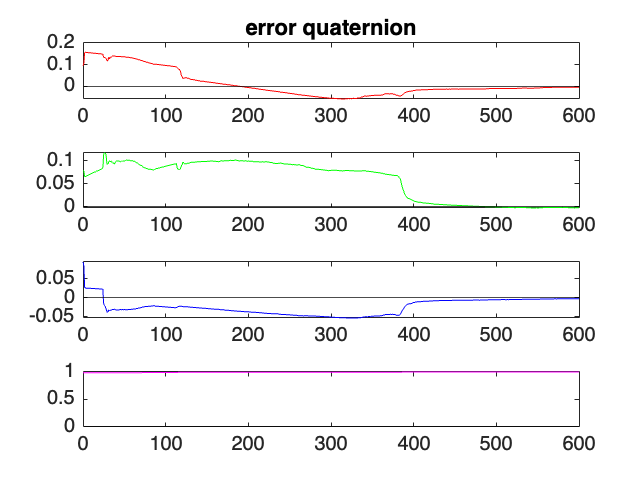

savedir = strcat(curdir, '/results/UKF/');

figname = "errorQuaternion";
figure('Name', figname)
tiledlayout(4,1), nexttile
plot(t_, qe(:,1), 'r');
yline(0, '-k');
xlim([0 t_(end,1)])
title('error quaternion');
nexttile;
plot(t_, qe(:,2), 'g');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe(:, 3), 'b');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe(:, 4), 'm');
yline(0, '-k');
xlim([0 t_(end,1)])
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

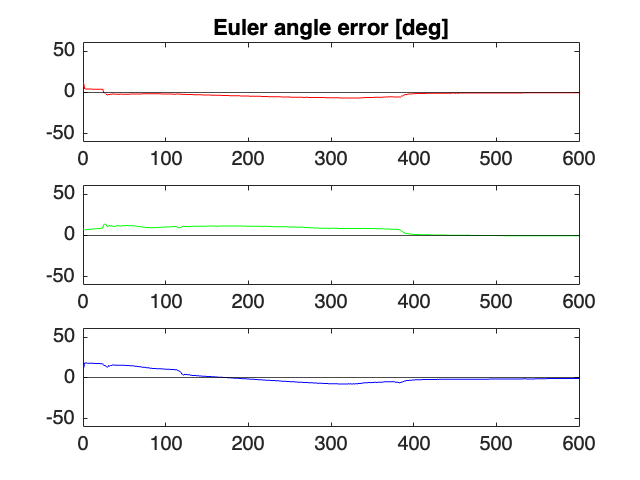


% figure
% tiledlayout(3,1), nexttile
% plot(t_/60, rad2deg(phiE), 'r'); % なんでt_/60をしてるの？
% title('Euler angle error [deg]');
% % xlim([0 60*6]), ylim([-60 60])
% xlim([0 t_(end,1)]), ylim([-60 60])
% nexttile
% plot(t_/60, rad2deg(thetaE), 'g');
% xlim([0 60*6]), ylim([-60, 60]);
% nexttile
% plot(t_/60, rad2deg(psiE), 'b');
% xlim([0 60*6]), ylim([-60 60]);

figname = "eulerAngleError";
figure('Name', figname);
tiledlayout(3,1), nexttile
plot(t_, rad2deg(phiE), 'r'); 
yline(0, '-k');
title('Euler angle error [deg]');
xlim([0 t_(end,1)]), ylim([-60 60])
nexttile
plot(t_, rad2deg(thetaE), 'g');
yline(0, '-k');
xlim([0 t_(end,1)]), ylim([-60, 60]);
nexttile
plot(t_, rad2deg(psiE), 'b');
yline(0, '-k');
xlim([0 t_(end,1)]), ylim([-60 60]);
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);